Rf = 0.06

Rf = 0.0600

sigma = 0.12

sigma = 0.1200

startPrice = 100

startPrice = 100

K = 100

K = 100

T = 200

T = 200

Delta = T/5 %lunghezza del passo

Delta = 40

year = 252

year = 252

t= Delta/year

t = 0.1587

u=exp(sigma*sqrt(t))

u = 1.0490

d=exp(-sigma*sqrt(t))

d = 0.9533

q=0.02

q = 0.0200

[call,put]=blsprice(startPrice,K,Rf,200/252,sigma,q)

call = 5.8485

put = 2.7730

simulazione

ExpReturn = [Rf];
Sigmas = [sigma^2];
correlation=[sigma^2]

correlation = 0.0144

ExpCovariance = sigma^2

ExpCovariance = 0.0144

NumObs=200;
NumSim= 100000;
RetIntervals=1/252;
rng('default');  
RetExpected = portsim(ExpReturn-q, ExpCovariance, NumObs,RetIntervals, NumSim, 'Expected');
ExpSimulation=squeeze(RetExpected);

trovo i prezzi azionari

clear StockPrices
clear TickTimes
clear TickSeries
StockPrices= ret2tick(ExpSimulation,repmat(startPrice,1,NumSim))

StockPrices =   100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
  100.1327   99.3902  100.5918  101.1104   99.5828   99.5377  101.9956  100.1277   99.7475   99.9865  101.9168  100.0445  100.5477   98.1764  101.9917  100.3022   99.3713  100.0565   99.7402  100.3460   98.9851  100.7983   99.6659  101.6065  100.2904   99.1082  100.0910  100.1818   99.8267   99.8616  100.7039  101.0751  100.6969   99.5243  100.2032   99.6186  100.7457   99.9454   99.5927   99.8015   99.4227  101.5724   99.7626   99.5638   99.4377  100.0956  101.1380  101.4754   98

istogramma

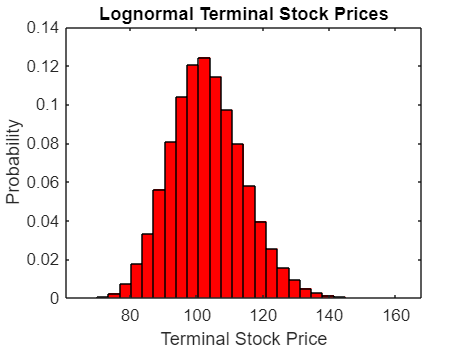

[count, BinCenter] = hist(StockPrices(end,:), 30);
figure(1)
bar(BinCenter, count/sum(count), 1, 'r')
xlabel('Terminal Stock Price')
ylabel('Probability')
title('Lognormal Terminal Stock Prices')

grafico

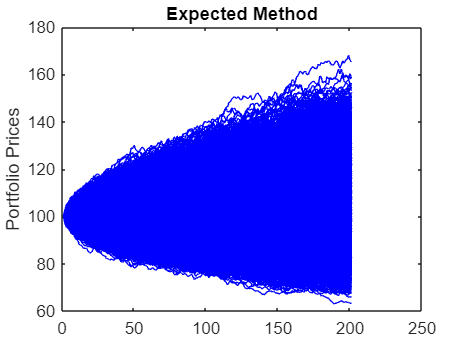

plot(StockPrices, '-b')
ylabel('Portfolio Prices')
title('Expected Method')

pricing call

term=StockPrices(201,:)';
payoff=(term-100);
payoff(payoff < 0) = 0

payoff =     8.9242
         0
    3.3306
         0
         0
    5.1323
   19.1611
    0.9185
         0
    6.2246


callmontecarlo=mean(payoff)/(1+Rf)

callmontecarlo = 5.8338

pricing put

payoff1=(100-term);
payoff1(payoff1 < 0) = 0

payoff1 =          0
    8.3848
         0
    3.7447
    1.0358
         0
         0
         0
    4.2240
         0


putmontecarlo=mean(payoff1)/(1+Rf)

putmontecarlo = 2.7314